clear

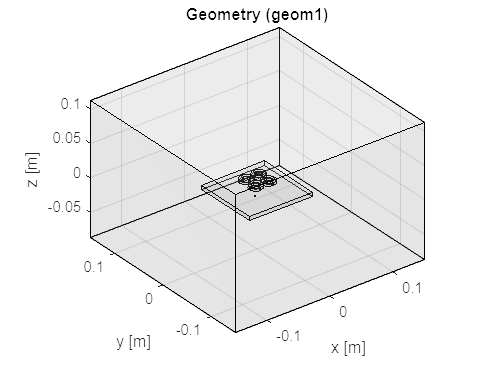

Plate.length = 100e-3; % (m)
Plate.height =   6e-3; % (m)
Plate.conductivity = 3.774e7; % (S/m)
Plate.relative_permeability = 1;
Plate.relative_permittivity = 1;
Plate = dividePlate(Plate, 50, 4);

Coil.width  = 20e-3; % (m)
Coil.height =  5e-3; % (m)
Coil.thickness = 5e-3; % (m)
Coil.fillet = 10e-3; % (m)
Coil.N_turns = 100;
Coil.positions = gridpoints( ...
    linspace(-10e-3,10e-3, 2), ...
    linspace(-10e-3,10e-3, 2), ...
    13e-3); % (m)
Coil.current = [1 1i -1i -1];

Sensor.side_length = 1e-3; % (m)
Sensor.positions = gridpoints( ...
    linspace(-17.5e-3,17.5e-3, 8), ...
    linspace(-17.5e-3,17.5e-3, 8), ...
    4e-3); % (m)

model = ComsolModel('Build', Plate, Coil, Sensor);

model.component('mod1').mesh('mesh1').autoMeshSize(5); % 1:finest 9:coarsest

% model.save(fullfile(pwd,'temp.mph'))
% writematrix(Sensor.positions.', 'sensor-position.txt')

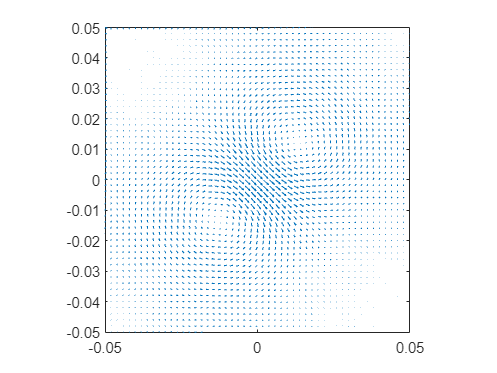

r = gridpoints( ...
    linspace(-Plate.length/2, Plate.length/2, 51), ...
    linspace(-Plate.length/2, Plate.length/2, 51), ...
    -Plate.height/2 );

model = ComsolModel('SolveCoil', model, Coil, 100);
E = InterpE(model, r);
figure
quiver(r(1,:), r(2,:), real(E(1,:)), real(E(2,:)))
xlim([-Plate.length/2 Plate.length/2])
ylim([-Plate.length/2 Plate.length/2])
axis square

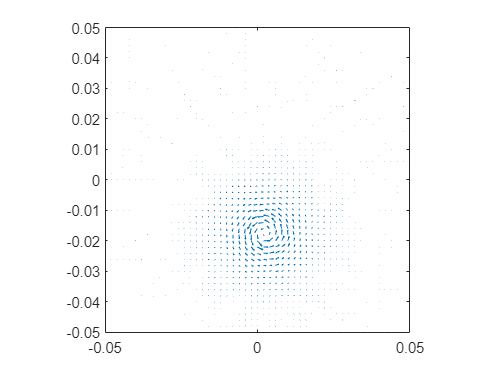


Sensor.pos = Sensor.positions(:,5);
Sensor.axis = [0 0 1];
model = ComsolModel('SolveSensor', model, Sensor, 100);
E = InterpE(model, r);
figure
quiver(r(1,:), r(2,:), real(E(1,:)), real(E(2,:)))
xlim([-Plate.length/2 Plate.length/2])
ylim([-Plate.length/2 Plate.length/2])
axis square


clear r E

S = ComputeSensivity(model, Plate, Coil, Sensor, 100);

Sensor 1 x-axis took 6.02 seconds
Sensor 1 y-axis took 5.83 seconds
Sensor 1 z-axis took 5.81 seconds
Sensor 2 x-axis took 6.20 seconds
Sensor 2 y-axis took 6.11 seconds
Sensor 2 z-axis took 6.05 seconds
Sensor 3 x-axis took 6.00 seconds
Sensor 3 y-axis took 5.97 seconds
Sensor 3 z-axis took 5.99 seconds
Sensor 4 x-axis took 6.02 seconds
Sensor 4 y-axis took 5.90 seconds
Sensor 4 z-axis took 6.00 seconds
Sensor 5 x-axis took 5.99 seconds
Sensor 5 y-axis took 5.91 seconds
Sensor 5 z-axis took 5.88 seconds
Sensor 6 x-axis took 5.96 seconds
Sensor 6 y-axis took 5.83 seconds
Sensor 6 z-axis took 5.85 seconds
Sensor 7 x-axis took 5.89 seconds
Sensor 7 y-axis took 5.86 seconds
Sensor 7 z-axis took 5.85 seconds
Sensor 8 x-axis took 5.87 seconds
Sensor 8 y-axis took 5.90 seconds
Sensor 8 z-axis took 5.82 seconds
Sensor 9 x-axis took 6.00 seconds
Sensor 9 y-axis took 6.08 seconds
Sensor 9 z-axis took 5.85 seconds
Sensor 10 x-axis took 5.97 seconds
Sensor 10 y-axis took 5.91 seconds
Sensor 10 z-


fname = sprintf('Sensivity_%s.mat', datetime('now','Format','MMdd-HHmm'));
element_positions = Plate.elems_center;
sensor_positions = Sensor.positions;

save(fname, 'S','element_positions','sensor_positions')

clear fname element_positions sensor_positions

function S = ComputeSensivity(model, Plate, Coil, Sensor, frequency)

S = zeros(size(Sensor.positions,2)*3, size(Plate.gauss_points,3));

model = ComsolModel('SolveCoil', model, Coil, frequency);
E1 = InterpE(model, Plate.gauss_points);

i = 1;
for sensor_num = 1:size(Sensor.positions,2)
for sensor_axis = 1:3
    tic
    Sensor.pos = Sensor.positions(:,sensor_num);
    Sensor.axis = zeros(1,3);
    Sensor.axis(sensor_axis) = 1;
    model = ComsolModel('SolveSensor', model, Sensor, frequency);
    E2 = InterpE(model, Plate.gauss_points);
    
    S(i,:) = sum(dot(E1,E2) .* Plate.gauss_weights, 2);
    i = i + 1;
    
    str = 'xyz';
    fprintf('Sensor %d %s-axis took %.2f seconds\n', sensor_num, str(sensor_axis), toc)
end
end

end

function E = InterpE(model, r)
[Ex,Ey,Ez] = mphinterp(model,{'mf.Ex' 'mf.Ey' 'mf.Ez'}, ...
                       'coord',reshape(r,3,[]), 'dataset','dset1');
E = reshape([Ex;Ey;Ez], size(r));
end

function r = gridpoints(x_points, y_points, z_points)
[x,y,z] = ndgrid(x_points,y_points,z_points);
r = [reshape(x,1,[]); reshape(y,1,[]); reshape(z,1,[])];
end

function Plate = dividePlate(Plate, n_l, n_h)
nodes = gridpoints( ...
    linspace(-Plate.length/2, Plate.length/2, n_l+1), ...
    linspace(-Plate.length/2, Plate.length/2, n_l+1), ...
    linspace(-Plate.height, 0, n_h+1) );

elems = zeros(8, n_l*n_l*n_h, 'uint16');
p = 1;
for k = 1:n_h
for j = 1:n_l
for i = 1:n_l
    elems(1,p) = (k-1) * (n_l+1) * (n_l+1) + (j-1) * (n_l+1) + i;
    elems(2,p) = elems(1,p) + 1;
    elems(3,p) = elems(2,p) + (n_l+1);
    elems(4,p) = elems(3,p) - 1;
    elems(5:8,p) = elems(1:4,p) + (n_l+1) * (n_l+1);
    p = p + 1;
end
end
end

elems_center = zeros(3, size(elems,2));
gauss_points = zeros(3, 0, size(elems,2));
gauss_weights = zeros(1, 0, size(elems,2));
for j = 1:size(elems,2)
    elem = elems(:,j);
    elem(elem==0) = [];
    elem_nodes = nodes(:,elem);
    elems_center(:,j) = mean(elem_nodes,2);

    [xis,weights] = GaussianQuadrature(size(elem_nodes,1), size(elem_nodes,2), 2);
    for l = 1:length(weights)
        xi = xis(:,l);
        N     = ShapeFunction(size(elem_nodes,1), size(elem_nodes,2), xi);
        dNdxi = ShapeFunction(size(elem_nodes,1), size(elem_nodes,2), xi, 'diff');
        x     = elem_nodes * N;
        dxdxi = elem_nodes * dNdxi;
        gauss_points(:,l,j) = x;
        gauss_weights(:,l,j) = det(dxdxi) * weights(l);
    end
end

Plate.elems_center  = elems_center;
Plate.gauss_points  = gauss_points;
Plate.gauss_weights = gauss_weights;
end